clear all, close all, clc

### HW02_2

Here, from Richardson Extrapolaion, we get-


$$\bar{f\;} =f_h +\frac{f_h -f_{\textrm{rh}} }{r^p -1}$$


Here, for this context

 $\bar{f\;} \;$= RE extropolated flux value

 $f_h$ = flux for refined mesh; $f_{\textrm{rh}}$ = flux for coarsest mesh

 r = refinement rate; p = order of scheme 

And error of the scheme is calculated by-


$$\varepsilon =-\frac{f_h -f_{\textrm{rh}} }{r^p -1}$$


The mesh dividings are

n =   [20,      40,      80,      160,     320];

So, we  have, the mesh size

h =   10./n

h =     0.5000    0.2500    0.1250    0.0625    0.0312


therefrom, the refinement ratio for each level of refinement would be

r =   [1,       2,       4,        8,      16];   

And the flux values for different schmes of Angular Approximations are- 

P08 = [1.68075, 1.68320, 1.68350, 1.68354, 1.68357];
P12 = [1.68120, 1.68370, 1.68420, 1.68424, 1.68127];
P16 = [1.68140, 1.68385, 1.68445, 1.68450, 1.68453];
P20 = [1.68141, 1.68400, 1.68455, 1.68470,  nan   ];
P24 = [1.68142, 1.68420, 1.68460, 1.68475,  nan   ];
P28 = [1.68143, 1.68421, 1.68465, nan   ,   nan   ];
P32 = [1.68144, 1.68422, 1.68470, nan   ,   nan   ];

Now, let's find the richardson exptrapolations for different Angular Approximation schemes with different level of discretization.

#### P08

for i = 1:5
f_08(i) = P08(i)+ ( P08(i) - P08(1) )/(r(i)^8 - 1);
end
f_08

f_08 =        NaN    1.6832    1.6835    1.6835    1.6836


Errors for this scheme- with different levels of discretization is-

for i = 1:5
err_08(i) = - ( P08(i) - P08(1) )/(r(i)^8 - 1);
end
err_08

err_08 = 1.0e-05 *

       NaN   -0.9608   -0.0042   -0.0000   -0.0000


Similarly, let's do this higher order schemes

**P12**

for i = 1:5
f_12(i) = P12(i)+ ( P12(i) - P12(1) )/(r(i)^12 - 1);
end
f_12

f_12 =        NaN    1.6837    1.6842    1.6842    1.6813


Errors for this scheme- with different levels of discretization is-

for i = 1:5
err_12(i) = - ( P12(i) - P12(1) )/(r(i)^12 - 1);
end
err_12

err_12 = 1.0e-06 *

       NaN   -0.6105   -0.0002   -0.0000   -0.0000


**P16**

for i = 1:5
f_16(i) = P16(i)+ ( P16(i) - P16(1) )/(r(i)^16 - 1);
end
f_16

f_16 =        NaN    1.6839    1.6845    1.6845    1.6845


Errors for this scheme- with different levels of discretization is-

for i = 1:5
err_16(i) = - ( P16(i) - P16(1) )/(r(i)^16 - 1);
end
err_16

err_16 = 1.0e-07 *

       NaN   -0.3738   -0.0000   -0.0000   -0.0000


**P20**

for i = 1:5
f_20(i) = P20(i)+ ( P20(i) - P20(1) )/(r(i)^20 - 1);
end
f_20

f_20 =        NaN    1.6840    1.6846    1.6847       NaN


Errors for this scheme- with different levels of discretization is-

for i = 1:5
err_20(i) = - ( P20(i) - P20(1) )/(r(i)^20 - 1);
end
err_20

err_20 = 1.0e-08 *

       NaN   -0.2470   -0.0000   -0.0000       NaN


**P24**

for i = 1:5
f_24(i) = P24(i)+ ( P24(i) - P24(1) )/(r(i)^24 - 1);
end
f_24

f_24 =        NaN    1.6842    1.6846    1.6847       NaN


Errors for this scheme- with different levels of discretization is-

for i = 1:5
err_24(i) = - ( P24(i) - P24(1) )/(r(i)^24 - 1);
end
err_24

err_24 = 1.0e-09 *

       NaN   -0.1657   -0.0000   -0.0000       NaN


**P28**

for i = 1:5
f_28(i) = P28(i)+ ( P28(i) - P28(1) )/(r(i)^28 - 1);
end
f_28

f_28 =        NaN    1.6842    1.6846       NaN       NaN


Errors for this scheme- with different levels of discretization is-

for i = 1:5
err_28(i) = - ( P28(i) - P28(1) )/(r(i)^28 - 1);
end
err_28

err_28 = 1.0e-10 *

       NaN   -0.1036   -0.0000       NaN       NaN


**P32**

for i = 1:5
f_32(i) = P32(i)+ ( P32(i) - P32(1) )/(r(i)^32 - 1);
end
f_32

f_32 =        NaN    1.6842    1.6847       NaN       NaN


Errors for this scheme- with different levels of discretization is-

for i = 1:5
err_32(i) = - ( P32(i) - P32(1) )/(r(i)^32 - 1);
end
err_32

err_32 = 1.0e-12 *

       NaN   -0.6473   -0.0000       NaN       NaN


Now, let's plot all these error values against the discretization level

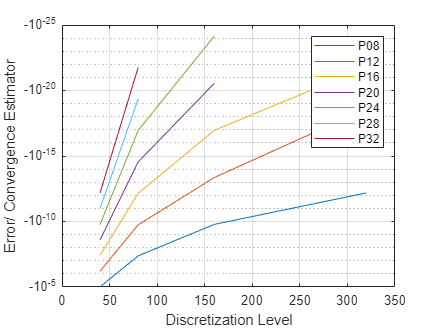

semilogy(n, err_08 ), grid on, hold on
semilogy(n, err_12 )
semilogy(n, err_16 )
semilogy(n, err_20 )
semilogy(n, err_24 )
semilogy(n, err_28 )
semilogy(n, err_32 )
legend('P08','P12', 'P16', 'P20', 'P24', 'P28', 'P32')
xlabel('Discretization Level')
ylabel('Error/ Convergence Estimator')

So, the above graph is a good estimator for the convergence of the schemes which are found through Richardson Extrapolation. It is found that, when the order of the Angular Approximation schemi is higher the convergance rate is also higher. On the other hand the values congerge to the exact value with the increase of discretization level. 

### HW02_3

Given,

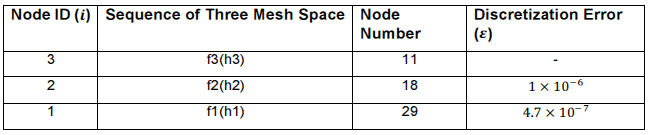

We know,


$$\varepsilon_1 =\frac{f_1 -f_2 }{r^{\hat{p\;} } -1}$$


$f_1 =$ function value for refined mesh; $f_2$ = function value for coarser mesh

r = refinement factor; $\hat{p\;}$ = observed order of scheme

Similarly,


$$\varepsilon_2 =\frac{f_2 -f_3 }{r^{\hat{p\;} } -1}$$


So, here,

eps = [4.7e-7, 1e-6, nan]

eps = 1.0e-06 *

    0.4700    1.0000       NaN


f_1 = 8.687e6;      % prssure value at 0.01TS and 29-grid; Pa
L = 3.7;            % domain length; m
n = [29, 18, 11];   % sorted from finest to coarsest grid (1, 2, 3)
h = L ./n           % mesh size; m

h =     0.1276    0.2056    0.3364


Then, let's define the ratios for different stepping in the grid-size 

r_12 = h(2)/h(1)

r_12 = 1.6111

r_23 = h(3)/h(2)

r_23 = 1.6364

So, the average of ratio of spatial discretization (RSD)

r = (r_23 + r_12)/2

r = 1.6237

Then formal order of accurcy could be approximated by-


$$p=\frac{\ln \;\left(\frac{\varepsilon_2 }{\varepsilon_1 }\right)}{\ln \left(r\right)}$$


Then from above equation, we get

p = log( eps(2)/eps(1) ) /log(r)

p = 1.5576

Now, as we have

$\varepsilon_1 =\frac{f_1 -f_2 }{{r_{12} }^p -1}$ and $\varepsilon_2 =\frac{f_2 -f_3 }{{r_{23} }^p -1}$

This can be used to find value of f_2

f_2 = f_1 - eps(1)*(r_12^p - 1)

f_2 = 8.6870e+06

f_2a = f_2 + eps(1)         % actual function value; Pa

f_2a = 8.6870e+06

Similarly

f_3 = f_2 - eps(2)*(r_23^p - 1)

f_3 = 8.6870e+06

f_3a = f_3 + eps(2)         % actual function value; Pa

f_3a = 8.6870e+06

Then the observed order of accuracy woudl be-

#### Method 1


$$\hat{p} =\frac{\ln \;\left(\frac{f_3 -f_2 }{f_2 -f_1 }\right)}{\ln \left(r\right)}$$


  f_r = (f_3 - f_2) /(f_2 - f_1);       % function ratio 
p_ht = log (f_r) / log(r)

p_ht = 1.6514

*(Ans)*

#### **Method 2**

We know the following for variable grid refinement factor

   ...eq-(A)

It was found before, approximate formal order of accruacy-

% p = 1.5576        % approximate formal OA

Now, let's run a iteration-loop to find the observed order of accuracy fron eq-(A)

err = 1; it = 0;    % initializers
tol = 1e-15;        % error tolerance for loop-breaker
while tol < err
    p_ht = log( (r_12^p -1) *f_r + r_12^p ) /log(r_12 *r_23);
    err = (p_ht - p) /p_ht;
    p = p_ht;       % reassignment
    it = it+1;      % iteration counter
end 
p_ht

p_ht = 1.5821

*(Ans)*

### Temporal

Given,

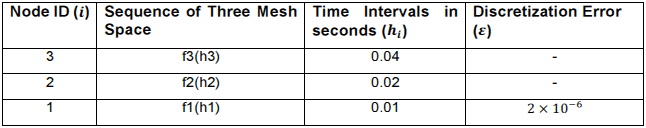

Let's find the temporal stuffs-

ts = 0.01;              % timestep; sec
t = [0.01, 0.02, 0.04]; % time intervals; sec

Let's find the time-interval ratio

rt_12 = t(2)/t(1)

rt_12 = 2

rt_23 = t(3)/t(2)

rt_23 = 2

  which are obviously constant

Now, we know,


$$r_t ={\left(r_x \right)}^{\frac{\hat{p\;} }{\hat{q\;} }}$$


r_t = ratio of temporal discretization; r_x = ratio of spatial discretization

$\hat{p\;}$ = Observed Order of accurcay (OOA) of spatial discretization

$\hat{q\;}$ = OOA of temporal discretization

So,

q_ht = p_ht *log(r) /log(rt_12)

q_ht = 1.1064

*(Ans)*